## 

# **Introduction to Matlab - Part 1**

## **Introduction**

In this course I hope to give you basic inroduction to Matlab and to get you comfortable with the software. 

If you have any specific research questions or you need help streamlining your code feel free to book a 1-hour one-to-one appointment with me using the link below.

[https://gemma-ives.appointlet.com/s/consultation](https://gemma-ives.appointlet.com/s/consultation) 

### **Learning Outcomes**

- **Create and manipulate data arrays**

- **Relational and logical indexing**

- **Create basic loops**

- **Create basic functions**

- **Handling multi-dimensional data**

# **Matlab Workspace**

**Instructional video: **

## **Scripting in Matlab**

Matlab scripts can be written, saved and distributed. New scripts can be opened from the home tab. 

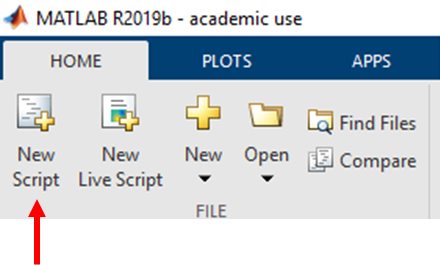

These scripts can be saved and run in the editor tab.

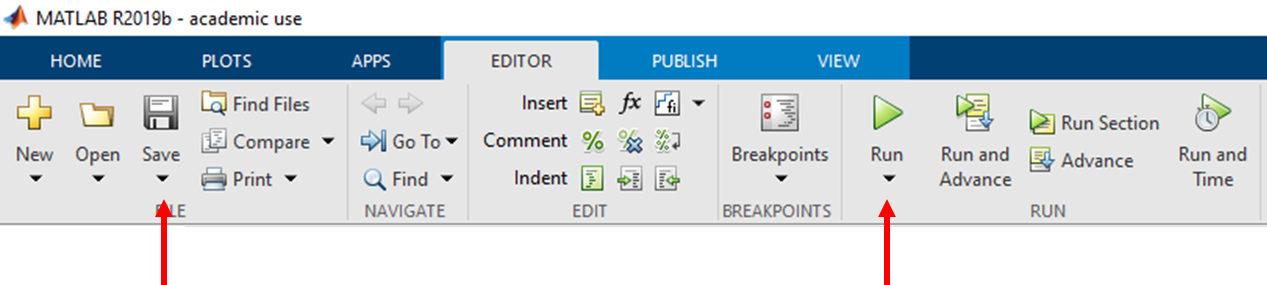

**Run the script MatlabLogo.m. **

You'll find this in the course docuemnts.

Note: Matlab doesn't read whitespace. This includes inline spaces, indentations and linespaces. But it's good practice to write clearly with clear consice comments throughout. Comments are denoted by %, Matlab doesn't read these lines. 

% Execute the following two lines of code
% This can be done by pasting into the command window, or highlighting and pressing f9. 

A=1+2;
    B = 1 +     2 ;

    
%Close your figure
close
%Clear you workspace
clear  
%Clear your command window
clc

# **Preliminaries**

## Vectors and Matrices

This section deals with the manual creation of vectors and matrices.

Arrays can be manually created using square brackets [ ]

- columns separated with a space

- rows separated by a ;

% Creating a 1x3 row vector
A = [1 2 3]

% Creating a 3x1 column vector
B = [sqrt(10); pi^2; sin(pi/4)]

% Creating a 3x2 Matrix
C = [4 5 6; 7 8 9]


There are many ways to create vectors in Matlab. Test each option below individually by highlighting and pressing F9.

% Using the colon notation
D = 1:10
% It is also possible to specify the iterations when using the colon notation. 
% The following code creates every second number between 1 and 10.
E = 1:2:10

% Using Matlab functions
% Linspace lets you specify the first, last and number of elements. 
F = linspace(1,10,5)
%Rand creates an n-dimensional array of random numbers between 0 and 1.
G = rand(5,1)

% Creating uniform arrays
I = zeros(2,2)
J = eye(3,3)
K = ones(4,4)
% NaN means 'not a number'. This is a very useful function which lets you create a blank array
% with a pre-defined size. 
L = nan(5,5)

Note: As you have been creating these variables they have been appearing in your command window. This read out is not necessary as the variables are saved to your workspace. Suppress these outputs by using a semicolon ; at the end of each line. 

% Have a go:
% Create a vector from 5 to 100 containing every fifth number. Assign it to the name M.


% Create a 4x5 matrix of random numbers. Assign it to the name N.



If you want to view these arrays, you can select them in your workspace, or call them from the command line using their names. Try this now. 

This will not be possible for large arrays or those with more than three dimensions. 

% View the variables in the workspace using who
who
%View details of the variable using whos
whos

% Clear your workspace
clear
% clear your command window 
clc

## **Extraction and Alteration of Arrays**

This section demonstartes . 

We'll start by creating a 6x4 matix of random numbers. Calling this variable 'Data'. 

Data = 100*rand(6,4);

Elements can be extracted from a varibale using brackets ( ). The first dimension are rows, the second dimension are columns. 

% Extract the specific datapoint from the third row, second column:
Data(3,2)

% The colon notation can select 'all'. 
% Extract all the rows in the 4th column
Data(:,4)

% Extract every second column and assign it to the varibale 'Subset'
Subset = Data(:,1:2:end); % end refers to the last element
% Extract the last three columns
Subset2 = Data(:,[2:4]);
% Extract the first two and last rows
Subset3 = Data([1 2 6],:);

Specific elements in a variable can be ammeded.

% Change the datapoint in the 4th row, second column of Subset.
Subset(4,2) = 10;

% Data can also be changed to NaN. Which is particularly useful if a datapoint is an error. 
Subset(2,1) = NaN;

% You can see the revised subset by calling it in the command window or
% opening it the variable viewer. 

Arrays can be transposed and flipped. 

% Arrays are transposed using ' 
SubsetTrans = Subset'
%Flipped using flipud (up down) or fliplr (left right)
SubsetFlip = flipud(Subset)
SubsetFlip2 = fliplr(Subset)

Arrays can be concatenated using the 'cat' function, or [ ] for multiple column vectors. The arrays to be concatentaed must be of equal length. 

% Have a go
% Extract the first and the last column separately from 'Data'. Assign them to SubsetA and SubsetB. 


% These new variables can then be concatenated horizontally
NewData = [SubsetA SubsetB]
NewData2 = cat(2, SubsetA, SubsetB) % Concatenate along the first dimension

% The can also be concatenated horizonatlly
Newdata3 = cat(1, SubsetA, SubsetB) % Note can can be used for n variables for n dimensions 

%Clear all except the Data variable
clearvars -except Data 

## Array Operations

This section wll cover some fundamental array operations. 

% Start by rounding the variable 'Data' to the nearest whole number.
DataRounded=round(Data);

% Perform basic operations
DS = DataRounded+10;
DD = DataRounded/10;
DM = DataRounded-10;
DT = DataRounded*10;

When performing operations between arrays and matrices, there is more to consider. 

Look at the behaviour of the multiply operation, we use a simple row and column vector to illustrate.

row=[1 2 3]
col=[4;5;6]
row*col
col*row
% Using a dot notation performs an elementwsie operation. 
col.*row
row.*col

Now try a matrix multiply, a pair of simple square matrices clearly illustrates correct matrix multiplication and the behaviour of the dot operator i.e. element wise operation

mat1=[1 2; 3 4]
mat2=[2 0; 0 2]

mat2*mat1
mat2.*mat1

It is also possible to perform basic operations accross array dimensions. 

% Add together the row vectors
TotalCol = sum(DataRounded, 2); 
s1 = size(TotalCol)% Total Col is a 6x1 column vector

% Average the data in each column
Av_Dat = mean(DataRounded, 1); 
s2 = size(Av_Dat) % Av Row is a 4x1

% find the max of the data in each column
Max_Dat = max(DataRounded)

%Find the min of the data in each row
Min_Dat = min(DataRounded, [], 2)

It's time to have a look at real world situation. The following 'have a go' section uses historical rainfall data from:

- Sheffield ([https://www.metoffice.gov.uk/pub/data/weather/uk/climate/stationdata/sheffielddata.txt](https://www.metoffice.gov.uk/pub/data/weather/uk/climate/stationdata/sheffielddata.txt)) 

- Peninsular India ([https://www.tropmet.res.in/DataArchival-51-Page](https://www.tropmet.res.in/DataArchival-51-Page)) 

Each dataset comprises of monthly rainfall averages per year from 1901-2014. Try to compare the average monthly rainfall in both areas. 

The comments should guide your analysis, but feel free to practice any of the methods that we have covered so far.

% Have a go:
% Compare monthly rainfall in the UK with Kerala, India. 
% Import rainfall data. 
Sheffield_Rain = load('Sheffield_Rain.csv');
India_Rain = load('SouthIndia_Rainfall.csv');

% Investigate your data. As the data set is small you can open it in
% variabile viewer. However you could practice requesting the size of the
% variable, or reading subsets to your command window. 

%Create a subset of each rainfall series which includes only those columns
%with rainfall data.



% The Indian rainfall series is in tenths of a millimetre. Convert to millimetres by
% dividing each point by 10



% The column vectors contain monthly rainfall, find the average monthly
% rainfall over the 114 years. 




% You should be able to create the following graph using your monthly
% rainfall averages. Where India_Monthly and Sheffield_Monthly are your
% variables for the long term monthly means. 
bar([1:12],cat(1, India_Monthly, Sheffield_Monthly),'grouped')
legend('South India', 'Sheffield')
ylabel('Rainfall (mm)')


% Tidy up the workspace by clearing unused variables.
% Keep Sheffield_Rain, we'll be using this later.
clearvars -except Sheffield_Rain

# Relational and Logical Operations

These are particularly useful and are excellent for creating fast, efficient code. We'll spend a bit of time here. 

Relational and Logical Operatiors allow you to query the data within a variable against a condition or set of conditions and return true or false values. 

Matlab represents true and false with the integers 0 and 1.

% Create a random array
Data = round(100*rand(5));

% Below is a list of relations
op1 = Data == 50; % Is rainfall in any month equal to 50?
op2 = Data ~= 50; % Is rainfall in any month not equal to 50?
op3 = Data > 50; % Is rainfall in any month greater than 50?
op4 = Data < 50; % Is rainfall in any month less than 50?
op5 = Data >= 50; % Is rainfall in any month greater than or equal to 50?
op6 = Data <= 50; % Is rainfall in any month less than or equal to 50?

The result of these statements is a variable with a class of logical, comprising of true and false values (0 and 1). Take a look at ans (answer) in the variable viewer. 

This logical array can be used to maipulate variables. 

% Change all values in Data which exceed 50 to 100 
% First take a look at the components
Data
op3

% The logical array indexes to values that meet the argument.
% You can change these values values by assigning the new number to them.
Data(op3) = 100;


We may combine logical tests, as one might expect, & represents 'and' and (not so clearly) a vertical bar | means or; 

Data > 50 & Data < 99  %logical 'and'
Data > 75 | Data == 100  %logical 'or'

Finally, as well as manipulating data, we can also extract subsets using logical indexing. 

% Find those values in Data that are not equal to 
Subset1 = Data(Data ~= 100);

% If you want to preserve the dimensions of the original data in your subset you can
% extract to a predefined array.
Subset2 = NaN(size(Data)) %Create a NaN array with the dimansions of Data
Subset2(Data~=100) = Data(Data~=100)

Logical indexing is fast, powerful and exceptionally useful, try the following task and if you have any questions please ask.

Task: Using Sheffield_Rain, find those months with rainfall greater than 5mm but less than 10mm, assign them to a new variable called Target_Rainfall.

% Have a go:
% Remember to make a copy of Sheffield_Rain to save you re-importing your data if you make a mistake.
 


% When you're done clear up your workspace
clear

# Programming Constructs

## Using Loop Control and Conditional Statements

There are occasions when we want to repeat a segment of code a number of different times (such occasions are less frequent than other programming languages because of the : notation).

### For loops

The for loop will repeat the set of commands between for and end. The loop will repeat equal to the number of intervals defined in the varibale beside `for`. 

%Preallocate your array
Data=0
for ii=1:5 % Defines the iterations
   Data=Data+ii % Perfoms the command 
end % Completes the loop


It is possible to assign the output when looping, I've left the ; off the following example to show the construction of using a loop Data2. Scroll up to look at the reults of each loop iteration. 

% Preallocate your array
Data2 = nan(5,1);
for ii = 1:5
    Data2(ii,1) = 100/ii
end

For loops can also index into another varibale, the exmaple below uses dummy data to demonstrate how this can be used. 

In this example, we want to work out the total income from daily sales of items of differing prices, 50p 75p and £1.06.

Sales = [100*rand(10,3)];
Price = [.50 .75 1.06];

% Preallocate your output
Income = nan(1,3);

for ii = 1:3 % Initiate your loop
    Income(ii) = Price(:,ii)*(sum(Sales(:,ii))); % Multiply the nth price of the item by the nth column
end

Looping is a very useful tool, however it's important to remember that they aren't always necessary. Always think carefully before using loops, they can make your code less effiecient.

### If / else blocks

These code blocks allows us to execute different commands depending on the result of a logical test. 

The general structure of an if block is as follows

A = 100*rand(25,1); % Create some random data

if any(A < 50) %Conditional statement if any element of A is less than 50 then...
    disp('At least one element in A is less than 50') % Display a statement. 
end

If blocks can also be combined with an else and/or and elseif statement to increase the expressions which can be tested. In the example below, the if block tests whether any elements in A are less than or equal to 5. If so, it squares every element in A. It also tests whether any element is equal to 20, which would aslo trigger statement B = A.^2. Finally, if neither expressions are met, the statement under else will trigger, ensuring that there is always data in B.

A = [1:10];
if any(A<=5)
    B = A.^2;
elseif any(A == 20)
    B = A.^2;
else
    B= NaN;
end

You can combine if/else/elesif blocks with for loops to pass the conditions over each element of an array individually. For example, the if block below doubles the radius of those circles whose area is below 500cm^2 and halves the radius of those above 500cm^2. 

Radius = 50*(rand(30,1));

New_Radius = nan(30,1);
for ii = 1:length(Radius)
    if (pi*Radius(ii).^2) < 500
       New_Radius(ii) = Radius(ii)*2;
    else 
       New_Radius(ii) = Radius(ii)/2;
    end
end

%Concatenate New_Radius and Radius to look at the new arrays (assign to a new varibale called changes). 




#### While Loop

There are some occasions when we want to repeat a section of Matlab code until some logical condition is satisfied, but we cannot tell in advance how many times we have to go around the loop. This we can do with a while...end construct.

Example: What is the greatest value of n that can be used in the sum:

x+(y^2) + (y+1)^2

and get a value of less than 200?

x = 1; y = 1;
while x + (y+1)^2 < 200
    y = y+1; 
    x = x + y^2
end
[y, x]

Loops, and if/else blocks are powerful tools for data science. To draw all this together, use the UK_Silage and UK_Hay data sets to investigate high and low production years for hay and silage, two grass based animal feeds. The data are matrices with the dimensions of 25x2; the first column contains a vector of years from 1992 to 2016, the second column contains UK wide production of each feed in tonnes. 

% Import data
Hay = load('UK_Hay.csv');
Silage = load('UK_Silage.csv');

% Find the average tonnage of both Hay and Silage over the 25 years. Assign them the variables Hay_Mean and Silage_Mean



% Use a for loop and an if block to assign each element above the average a value of 1 and a value of -1 for each element below the average.
% Preassign your arrays, call them Index_Hay and Index_Silage













%With your new datasets you can investgate the relationship between low
%yeild years. 

% Use logical indexing to extract the years where yeilds of hay and silage
% are not classified with the same value.








